clc,clear,close all

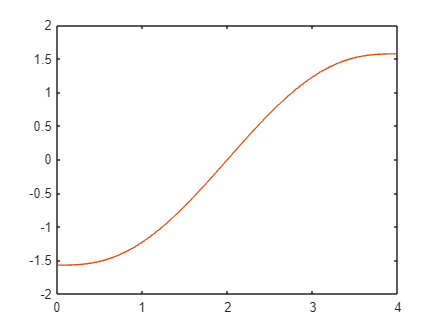

% Dynamical Model of two link Planar Manupulator 

% motor properties
amax=1.05; %[rad/s^2]
mm = [0.3, 0.3];
Im = [1, 1];
kr = [1/10,1/5];

% link dimension
lx=[1 1];
ly=[1 1];
lz=[1 1];

%material properties
density=2660; % [kg/m3] AW 5083 alloy
rho=(density*1000)/100^3; %[g/cm3]

mass=[rho*lx(1)*ly(1)*lz(1) rho*lx(2)*ly(2)*lz(2)];

% simulation parameters
methods = dynlib;
Tf = 4;
t_step = 0.01;
[A, ~] = methods.criticaltrajectory(Tf, amax);
t = [0:0.01:Tf];
y = [];
for i=1:length(t)
    y=[y;A'*methods.vand(t(i), 7)', A'*methods.devand(t(i),7)', A'*methods.dedevand(t(i),7)'];
end
u = [y(:,1)'; y(:,1)']; % control both the motors in the same way
plot(t, u)


methods =dynlib;
syms("q1", "q2", "dq1", "dq2");
q = [q1, q2];
dq = [dq1, dq2];
[Bq, Cq, gq] = methods.dyn(lx, ly, lz, rho, mm, Im, kr);
F = [0 0; 0 0]; % TEMP

% Simulation
qt = [0;0];
dqt = [0;0];
ddqt = [0;0];
actual_q = [];
for i = 1:length(t)
    B = double(subs(Bq, q, qt'));
    C = double(subs(Cq, [q, dq], [qt', dqt']));
    g = double(subs(gq, q, qt'));
    ut = u(i,:);
    sim("SimulationSS");
    actual_q = [actual_q; out.q];
end

Error due to multiple causes.

Caused by:
    Error using dimensioning_opt
    Error in port widths or dimensions. Invalid dimension has been specified for 'Input Port 2' of 'SimulationSS/Sum1'.
    Error using dimensioning_opt
    Error in port widths or dimensions. 'Output Port 1' of 'SimulationSS/Integrator1' has 2 elements.  This port does not accept the di

%{
methods = dynlib;
t_end = 4;
[A, ~] = methods.criticaltrajectory(t_end, amax);
%A = methods.polynomial([-pi/2; 0; pi/2], [0; 0], [0; amax; 0], [0, t_end/2, t_end], [0, t_end], [0, t_end/4, t_end]);
t = [0:0.01:t_end];
y = [];
for i=1:length(t)
    y=[y;A'*methods.vand(t(i), 7)', A'*methods.devand(t(i),7)', A'*methods.dedevand(t(i),7)'];
end
plot(t,y);
legend("q", "q\_dot", "q\_ddot");
%}

%{
[B, C, g] = methods.dyn(lx,ly,lz,rho, mm, Im, kr)
syms("q1","q2","dq1","dq2");
Bq=simplify(subs(B,[q1,q2,dq1,dq2],[pi/2,pi/2,0.1,0.1]))
Cq=simplify(subs(C,[q1,q2,dq1,dq2],[pi/2,pi/2,0.1,0.1]))
%}

%{
% starting the simulation
methods = dynlib;
Tf = 4;
step_size = 0.01;
t = [0:step_size:Tf];

syms("q1", "q2", "dq1", "dq2");
q = [q1, q2];
dq = [dq1, dq2];

q_current = [0; 0];
dq_current = [0; 0];
ddq_current = [0; 0];

[Bq, Cq, gq] = methods.dyn(lx, ly, lz, rho, mm, Im, kr);
F = [0 0; 0 0]; % TEMP

A = methods.criticaltrajectory(Tf, amax);

y = [];
for i=1:length(t)
    y=[y;A'*methods.vand(t(i), 7)', A'*methods.devand(t(i),7)', A'*methods.dedevand(t(i),7)'];
end

q_actual = [];

for i = 1:length(t)
    B = double(subs(Bq, q, q_current'));
    C = double(subs(Cq, [q, dq], [q_current', dq_current']));
    g = double(subs(gq, q, q_current'));
    u = y(i, 3);
    sim("Simulation");
    q_current = out.q;
    dq_current = out.dq;
    ddq_current = out.ddq;
    q_actual = [q_actual; q_current'];
end

plot(t, q_actual, t, y(i, 1));

%}


























































